#  3. Building Classification Models

## Supervised Learning

Course Example: Heart Disease

load('heartdisease.mat')

[g,c] = kmeans(zscore(heartdataNum{:,1:11}),2)

g =      1
     2
     2
     1
     1
     1
     2
     1
     2
     2


c =    -0.5087   -0.2327    0.7028    0.7460    0.0422   -0.4646   -0.2767    0.6673    0.0154   -0.4265   -0.4793
    0.4316    0.1975   -0.5963   -0.6330   -0.0358    0.3942    0.2348   -0.5662   -0.0130    0.3619    0.4067


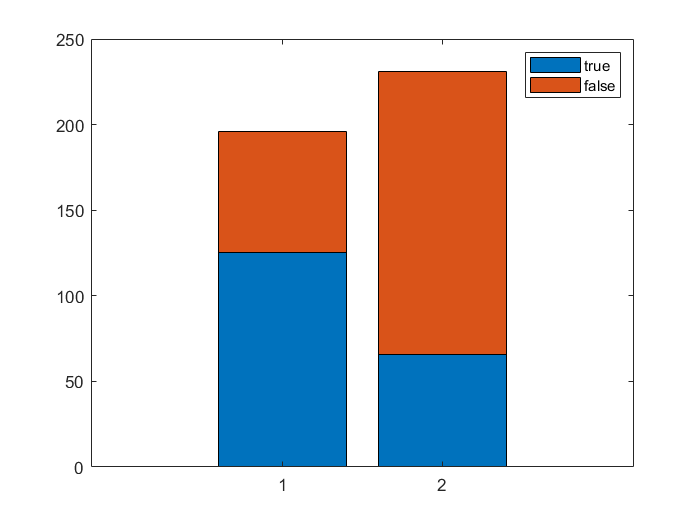

counts = crosstab(g,heartdataNum.HeartDisease);
figure
bar(counts,'stacked')
legend([{'true'},{'false'}])

### Training and Validation

% Divide the heart disease into training(80%) and validation(20%) sets
rng(1234)
part = cvpartition(heartdataNum.HeartDisease,'HoldOut',0.2);
tridx = training(part);
tdata = heartdataNum(tridx,:);
vdata = heartdataNum(~tridx,:);
tdataAll = heartdataAll(tridx,:);
vdataAll = heartdataAll(~tridx,:);


### 1. Nearest Neighbor Classification(1/2)

The most straightforward way of classification without any assumptions about the underlying distribution of the data

mdl = fitcknn(tdata,'HeartDisease');
% Why use tdata, not tdataAll? because k-NN does not accept mixed predictors(numeric+categorical).

### Evaluating Classifications

mdl = fitcknn(tdata,'HeartDisease')

mdl =   ClassificationKNN
           PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: []
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


errKNN_train = resubLoss(mdl)

errKNN_train = 0

errKNN_test = loss(mdl,vdata)

errKNN_test = 0.3413

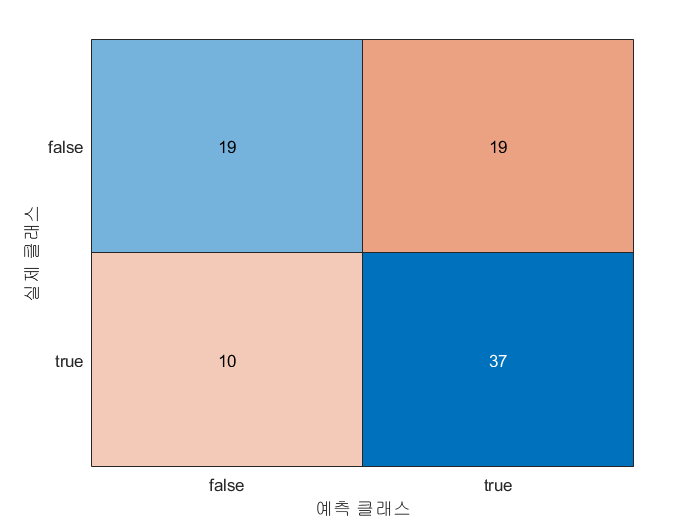


%Visualize prediction accuracy
HDpred = predict(mdl,vdata);
HDtrue = vdata.HeartDisease;
figure
confusionchart(HDtrue,HDpred)

### 1. Nearest Neighbor Classification(2/2)

mdl = fitcknn(tdata,'HeartDisease','NumNeighbors',5)

mdl =   ClassificationKNN
           PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: []
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods


errKNN_train = resubLoss(mdl)

errKNN_train = 0.2222

errKNN_test = loss(mdl,vdata)

errKNN_test = 0.2471

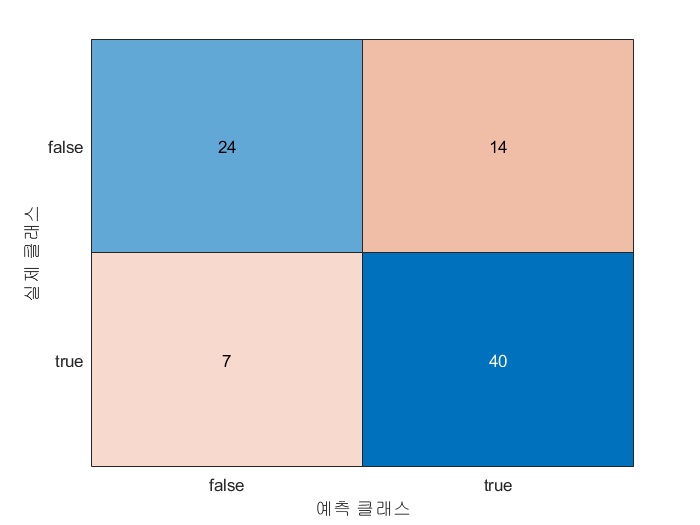

HDpred = predict(mdl,vdata);
HDtrue = vdata.HeartDisease;
figure
confusionchart(HDtrue,HDpred)

### 2. Decision Tree Classification

A decision tree model make a categorical response prediction by following a sequence of binary decisions based on predictor variable value. It does not assume any underlying distributions of the data like k-NN.

A decision tree model is robust to noise data.

mdl = fitctree(tdata,'HeartDisease')

mdl =   ClassificationTree
           PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: []
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342


  Properties, Methods


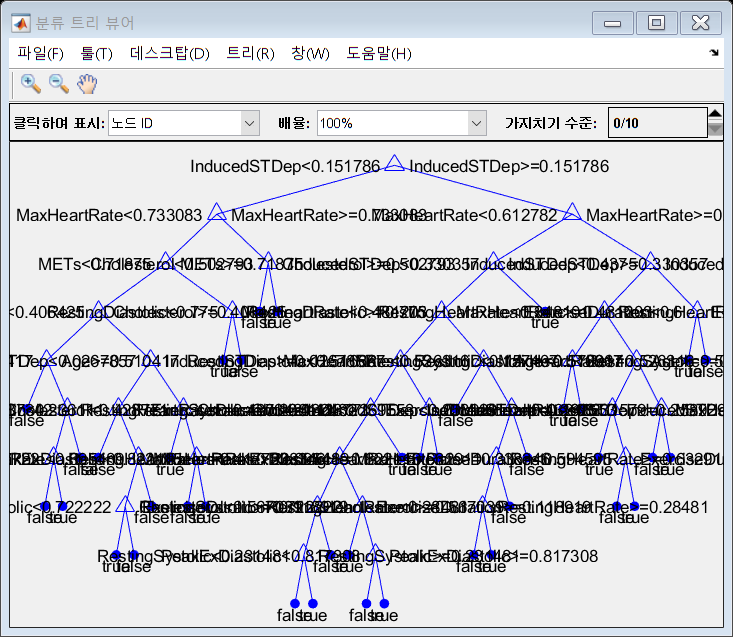

view(mdl,'Mode','graph')

errTree_train = resubLoss(mdl)

errTree_train = 0.0789

errTree_test = loss(mdl,vdata)

errTree_test = 0.2824


mdl = prune(mdl,'Level',3)

mdl =   ClassificationTree
           PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: []
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342


  Properties, Methods


view(mdl,'Mode',"graph")
errTree_train = resubLoss(mdl)

errTree_train = 0.1404

errTree_test = loss(mdl,vdata)

errTree_test = 0.2000


mdl = fitctree(tdataAll,'HeartDisease')

mdl =   ClassificationTree
           PredictorNames: {1×21 cell}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: [12 13 14 15 16 17 18 19 20 21]
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342


  Properties, Methods


errTree_train = resubLoss(mdl)

errTree_train = 0.0556

errTree_test = loss(mdl,vdataAll)

errTree_test = 0.2353


mdl = prune(mdl,'Level',3);
errTree_train = resubLoss(mdl)

errTree_train = 0.1082

errTree_test = loss(mdl,vdataAll)

errTree_test = 0.2118

### 3. Naive Bayes Classification

A Naive Bayes model uses Bayes's rule of conditional probability to estimate the probability of a given observation being in each response class. Accordingly, it assumes an underlying distribution of the data. (Note: Each predictor variable should be independent, If not, use a 'Discriminant Analysis')

mdl = fitcnb(tdata,'HeartDisease')

mdl =   ClassificationNaiveBayes
            PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
              ResponseName: 'HeartDisease'
     CategoricalPredictors: []
                ClassNames: [false    true]
            ScoreTransform: 'none'
           NumObservations: 342
         DistributionNames: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {2×11 cell}


  Properties, Methods


errNB_train = resubLoss(mdl)

errNB_train = 0.2982

errNB_test = loss(mdl,vdata)

errNB_test = 0.2000


dists = [repmat({'kernel'},1,11) repmat({'mvmn'},1,10)]

dists = 1×21 cell 배열
    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'kernel'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}    {'mvmn'}


mdl = fitcnb(tdata,'HeartDisease','DistributionNames','kernel');
errNB_train = resubLoss(mdl)

errNB_train = 0.2602

errNB_test = loss(mdl,vdata)

errNB_test = 0.1765


mdl = fitcnb(tdataAll,'HeartDisease');
errNB_train = resubLoss(mdl)

errNB_train = 0.2047

errNB_test = loss(mdl,vdataAll)

errNB_test = 0.1177


mdl = fitcnb(tdataAll,'HeartDisease','DistributionNames',dists);
errNB_train = resubLoss(mdl)

errNB_train = 0.1959

errNB_test = loss(mdl,vdataAll)

errNB_test = 0.1412

### 4. Discriminant Analysis - 각각의 predicter들이 독립적이든 독립적이지 않든 신경 쓰지 않느다.  

Similar to Naive Bayes, discriminant analysis works by assuming that the observations in each prediction class can be modeled with a normal probability distribution. However, there is no assumption of independence in each predictor.

mdl = fitcdiscr(tdata,'HeartDisease')

mdl =   ClassificationDiscriminant
           PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: []
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342
              DiscrimType: 'linear'
                       Mu: [2×11 double]
                   Coeffs: [2×2 struct]


  Properties, Methods


errDA_train = resubLoss(mdl)

errDA_train = 0.2719

errDA_test = loss(mdl,vdata)

errDA_test = 0.1765


mdl = fitcdiscr(tdata,'HeartDisease','DiscrimType',"quadratic")

mdl =   ClassificationDiscriminant
           PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: []
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342
              DiscrimType: 'quadratic'
                       Mu: [2×11 double]
                   Coeffs: [2×2 struct]


  Properties, Methods


errDA_train = resubLoss(mdl)

errDA_train = 0.2485

errDA_test = loss(mdl,vdata)

errDA_test = 0.2706

### 5. Support Vector Machines - 전반적으로 모든 경우에 있어서 항상 상위권의 분류기 정확도 - reponse가 2개 인 경우  

A SVM model classifies data by finding the best hyperplane that separates all data points

It only works for binary categories (true/false, 0/1, pass/fail)

mdl = fitcsvm(tdata,'HeartDisease')

mdl =   ClassificationSVM
           PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
             ResponseName: 'HeartDisease'
    CategoricalPredictors: []
               ClassNames: [false    true]
           ScoreTransform: 'none'
          NumObservations: 342
                    Alpha: [236×1 double]
                     Bias: 0.4054
         KernelParameters: [1×1 struct]
           BoxConstraints: [342×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [342×1 logical]
                   Solver: 'SMO'


  Properties, Methods


errSVM_train = resubLoss(mdl)

errSVM_train = 0.3012

errSVM_test = loss(mdl,vdata)

errSVM_test = 0.1647


mdl = fitcsvm(tdata,'HeartDisease','KernelFunction',"gaussian");
errSVM_train = resubLoss(mdl)

errSVM_train = 0.2602

errSVM_test = loss(mdl,vdata)

errSVM_test = 0.1647

### 5. Multiclass Support Vector Machines - 기본 svm 자체로는 reponse variable이 2개일 경우에만 사용 가능 하지만 svm을 사용할 일은 거의 없을것. msvm도 2개에서 사용 가능 

Multiclass SVM by creating an error-correcting output codes (ECOC).

mdl = fitcecoc(tdata,'HeartDisease');
errMSVM_train = resubLoss(mdl)

errMSVM_train = 0.3012

errMSVM_TEST = loss(mdl,vdata)

errMSVM_TEST = 0.1647


t = templateSVM('KernelFunction','gaussian')
mdl = fitcecoc(tdata,'HeartDisease','Learners',t)
errGaussianMSVM_train = resubLoss(mdl)
errGuussianMSVM_test = loss(mdl,vdata)


